# Stubbornness

The pivot of the project. This notebook establishes what stubbornness IS, proves numerically that pure averaging cannot express it, and shows what has to change for it to appear.

% Bootstrap: walk up from this file until setup_paths.m is found, then put
% the library on the path. This works whether you are running the .m source
% or the generated .mlx, from any folder.
projectDir = fileparts(mfilename('fullpath'));
while ~isfile(fullfile(projectDir, 'setup_paths.m')) && ...
        ~strcmp(projectDir, fileparts(projectDir))
    projectDir = fileparts(projectDir);
end
addpath(projectDir);
setup_paths;

NDS opinion-dynamics library added to the path.
Project root: /Users/llp/Desktop/NDS_Project


## Four notions that are routinely conflated

A glossary first, because the literature uses the same words differently. Parsegov et al. (2017) call FJ-prejudiced agents "stubborn", the tutorial's stubborn agents "totally stubborn", and P-independent agents "oblivious".

## Notion 3 is not stubbornness: inertia changes the rate, not the limit

A very self-confident agent converges to exactly the same consensus as a wide-open one; it merely takes longer. This is the clearest way to see that moving weight onto the diagonal does NOT create a stubborn agent.

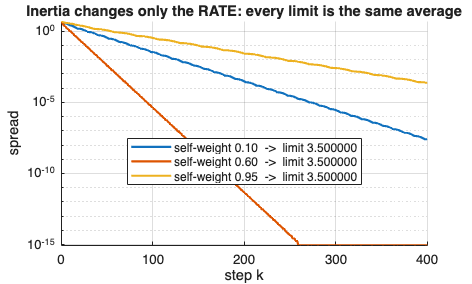

x0 = (1:6).';
selfWeights = [0.1 0.6 0.95];
limits = zeros(numel(selfWeights), 1);

figure; hold on; grid on;
for k = 1:numel(selfWeights)
    ring = make_ring(6, 'SelfWeight', selfWeights(k));
    r = sim_degroot(ring, x0, 400);
    spread = max(r.X, [], 1) - min(r.X, [], 1);
    semilogy(r.t, max(spread, eps), 'LineWidth', 1.6, ...
        'DisplayName', sprintf('self-weight %.2f  ->  limit %.6f', selfWeights(k), r.xinf(1)));
    limits(k) = r.xinf(1);
end
set(gca, 'YScale', 'log'); xlabel('step k'); ylabel('spread');
title('Inertia changes only the RATE: every limit is the same average');
legend('Location', 'best'); hold off;


fprintf('limits: %s   (all equal to the average %.6f)\n', ...
    mat2str(round(limits.', 10)), mean(x0));

limits: [3.5 3.5 3.5]   (all equal to the average 3.500000)


## Why averaging cannot produce persistent disagreement

Three equivalent arguments, each illuminating a different facet.

1 CONVEXITY. A row-stochastic update maps x into the convex hull of its own entries, so the hull is nested and shrinking. On a rooted aperiodic graph it contracts to a point. 2 INVARIANT SUBSPACE. W*1 = 1 always, so the consensus manifold span{1} is invariant for EVERY row-stochastic model, and attractive whenever the graph is rooted and aperiodic. 3 SPECTRUM. rho(W) = 1 is always attained, and the limit operator W^inf = 1*p' has RANK ONE -- it cannot encode individual differences.

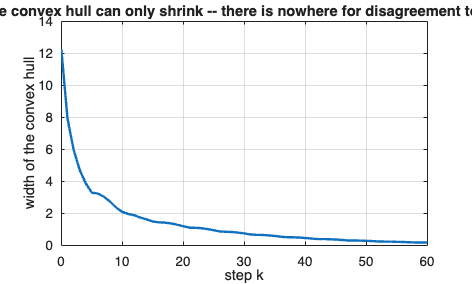

net = make_ring(8, 'SelfWeight', 0.2);
rng(0);                                   % reproducible figure
res = sim_degroot(net, randn(8, 1) * 3, 60);
hullWidth = max(res.X, [], 1) - min(res.X, [], 1);

figure;
plot(res.t, hullWidth, 'LineWidth', 1.8); grid on;
xlabel('step k'); ylabel('width of the convex hull');
title('The convex hull can only shrink -- there is nowhere for disagreement to live');


fprintf('hull width monotone non-increasing: %d\n', all(diff(hullWidth) <= 1e-12));

hull width monotone non-increasing: 1


fprintf('rank of the limit operator W^inf  : %d\n', ...
    rank(predict_limit_degroot_matrix(net.W)));

rank of the limit operator W^inf  : 1


## What has to break

The Friedkin-Johnsen model makes the update AFFINE instead of linear:

The homogeneous part Lambda*W is SUBSTOCHASTIC, so span{1} is no longer invariant and the consensus manifold simply disappears from the dynamics.

W = net.W;
lambda = 0.7 * ones(8, 1);
fprintf('\nW * 1        : %s   (invariant)\n', mat2str(round((W * ones(8,1)).', 4)));


W * 1        : [1 1 1 1 1 1 1 1]   (invariant)


fprintf('Lambda W * 1 : %s   (NOT invariant)\n', mat2str(round((lambda .* (W * ones(8,1))).', 4)));

Lambda W * 1 : [0.7 0.7 0.7 0.7 0.7 0.7 0.7 0.7]   (NOT invariant)



out = fj_matrices(W, lambda);
fprintf('rho(Lambda W) = %.6f  < 1, so the system is exponentially stable\n', out.rho);

rho(Lambda W) = 0.700000  < 1, so the system is exponentially stable


fprintf('rank(V) = %d of %d  -> every agent keeps a trace of its own prejudice\n', ...
    out.rankV, 8);

rank(V) = 8 of 8  -> every agent keeps a trace of its own prejudice


## More stability means less agreement

The eigenvalue that was pinned at 1, carrying the consensus mode, is pushed strictly inside the unit disc -- and with it the possibility of unanimity.

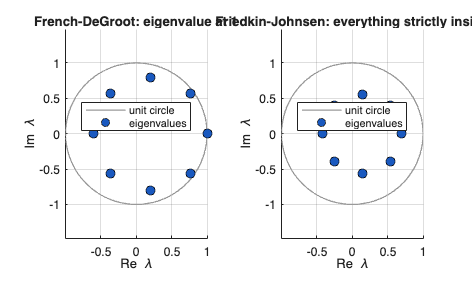

figure;
tl = tiledlayout(1, 2);
plot_spectrum(W, 'Axes', nexttile(tl), 'Title', 'French-DeGroot: eigenvalue at 1');
plot_spectrum(diag(lambda) * W, 'Axes', nexttile(tl), ...
    'Title', 'Friedkin-Johnsen: everything strictly inside');

## The alpha sweep: the whole story in one figure

With Lambda = alpha*I the family V_alpha = (1-alpha)(I - alpha W)^{-1} interpolates continuously between the two extremes:

So the persistent disagreement of the Friedkin-Johnsen model collapses CONTINUOUSLY into the consensus of French-DeGroot as agents become more susceptible. Stubbornness is not a binary property.

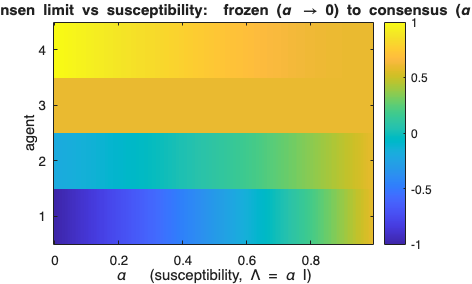

[fj, u] = make_example_fj4();
figure;
[Xinf, alphas] = plot_alpha_sweep(fj, u, [], 'Labels', fj.labels);

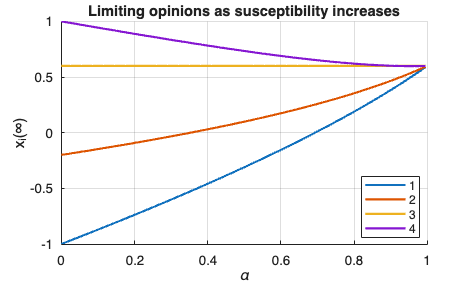


figure; hold on; grid on;
plot(alphas, Xinf.', 'LineWidth', 1.6);
xlabel('\alpha'); ylabel('x_i(\infty)');
title('Limiting opinions as susceptibility increases');
legend(fj.labels, 'Location', 'best'); hold off;

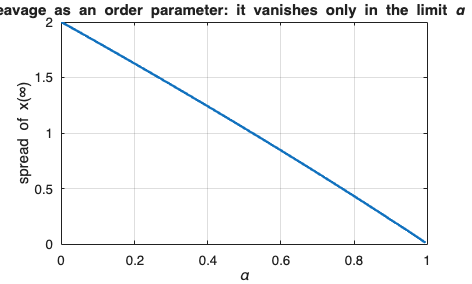


spread = max(Xinf, [], 1) - min(Xinf, [], 1);
figure;
plot(alphas, spread, 'LineWidth', 1.8); grid on;
xlabel('\alpha'); ylabel('spread of x(\infty)');
title('Cleavage as an order parameter: it vanishes only in the limit \alpha \rightarrow 1');

## Bounded, not divergent

Because V is row-stochastic, final opinions stay inside the convex hull of the prejudices. Friedkin-Johnsen produces CLEAVAGE, never runaway extremism. Escaping the hull requires negative ties, which is Part II material.

fprintf('\nprejudices span   : [%.3f, %.3f]\n', min(u), max(u));


prejudices span   : [-1.000, 1.000]


for a = [0.2 0.5 0.9]
    o = fj_matrices(fj.W, a, 'Warn', false);
    xi = o.V * u;
    fprintf('alpha = %.1f limits: [%.3f, %.3f]  inside hull: %d\n', ...
        a, min(xi), max(xi), min(xi) >= min(u) - 1e-12 && max(xi) <= max(u) + 1e-12);
end

alpha = 0.2 limits: [-0.738, 0.888]  inside hull: 1
alpha = 0.5 limits: [-0.310, 0.734]  inside hull: 1
alpha = 0.9 limits: [0.383, 0.601]  inside hull: 1


## ---------------------------------------------------------------------

function Winf = predict_limit_degroot_matrix(W)
%PREDICT_LIMIT_DEGROOT_MATRIX Limit operator, obtained column by column.
    n = size(W, 1);
    Winf = predict_limit_degroot(W, eye(n));
end